# Actividad 2.1 (Parametrización de trayectorias)

Oscar Ortiz Torres A01769292

clear all
close all
clc

## Parte 1 | Parametrización de trayectorias en un plano 2D

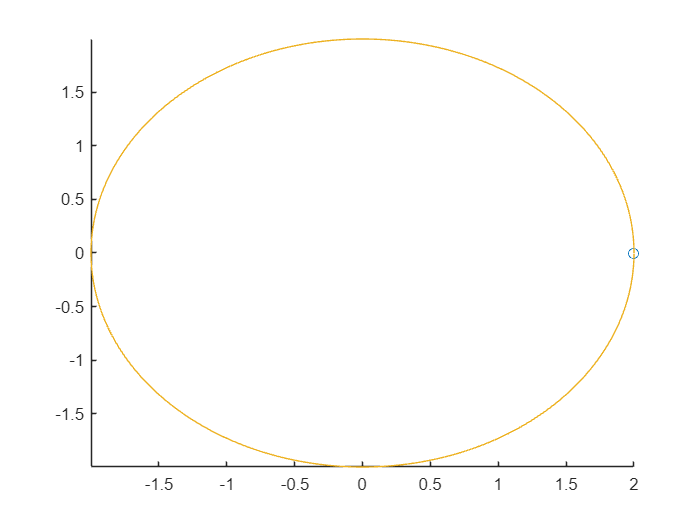

% Se define el parámetro "t" de parametrización sobre el cual se realizará
% la proyección de trayectoria
t = 0: 0.02: 2*pi;
% Se definen las funciones en 2D
x = 2*cos(t);
y = 2*sin(t);
comet(x,y);

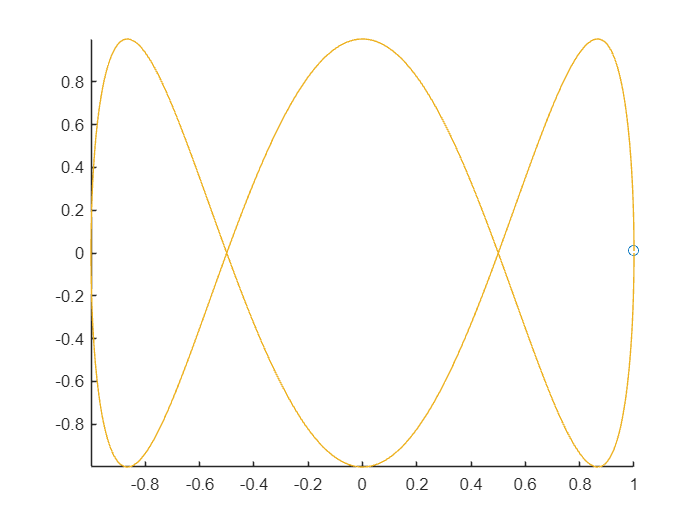

% Se define el parámetro "t" de parametrización sobre el cual se realizará
% la proyección de trayectoria
t = -2*pi: 0.02: 2*pi;
% Se definen las funciones en 2D
x1 = -cos(0.5*t);
y1 = sin(1.5*t);
comet(x1,y1);

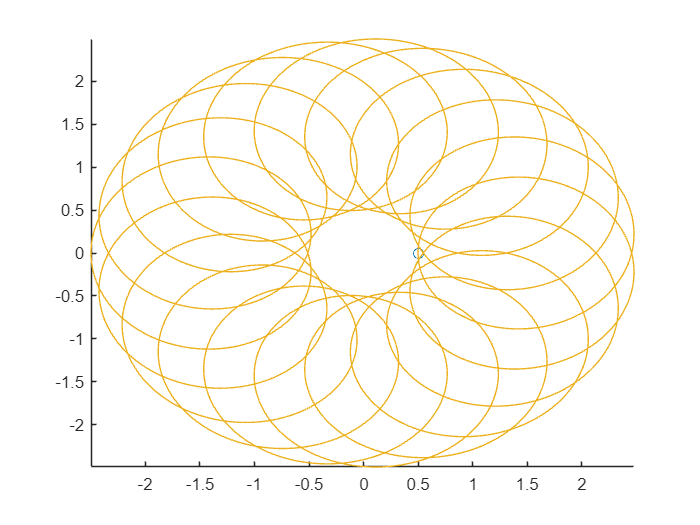

% Se define el parámetro "t" de parametrización sobre el cual se realizará
% la proyección de trayectoria
t = -10*pi: 0.01: 10*pi;
% Se definen las funciones en 2D
x2 = -1.5*cos(0.1*t) - cos(2*t);
y2 = 1.5*sin(0.1*t) + sin(2*t);
comet(x2,y2);

## Parte 2 |  Trayectorias definidas a partir de curvas paramétricas

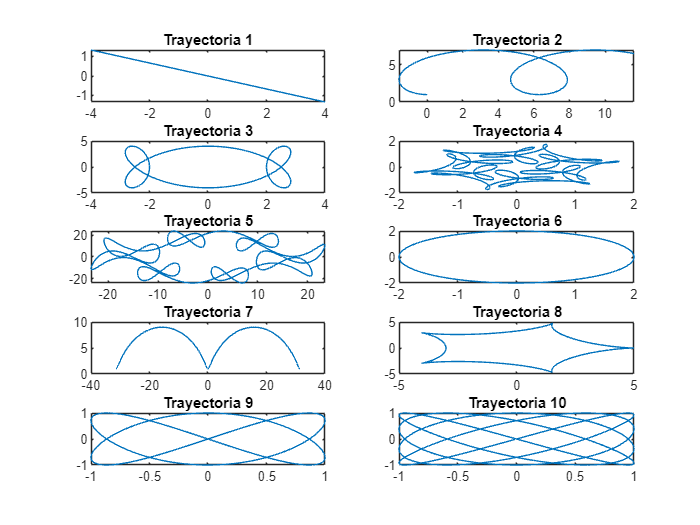

figure
syms t
x_vec=[2*t  ,t-3*sin(t)  ,3*cos(t)-cos(3*t)  ,cos(t)+1/2*cos(7*t)+1/3*sin(17*t)  ,17*cos(t)+7*cos(17+7*t)  ,2*cos(t)  ,5*t-4*sin(t)  ,4*cos(t)+cos(4*t)  ,sin(2*t)  ,sin(4*t)];
y_vec=[(t-3*t)/3  ,4-3*cos(t)  ,4*sin(3*t)  , sin(t)+1/2*sin(7*t)+1/3*cos(17*t)  , 17*sin(t)-7*sin(17*t)  ,2*sin(t)  ,5-4*cos(t)  ,4*sin(t)-sin(4*t)  ,sin(3*t)  ,sin(5*t)];
ti_vec=[-2  ,0  ,0  ,0  ,0  ,0  ,-2*pi  ,0  ,0  ,0];
tf_vec=[2  ,10  ,2*pi  ,2*pi  ,2*pi  ,14*pi  ,2*pi  ,2*pi,2*pi,2*pi];

hold on
for i=1:10
    % Se define el parámetro "t" de parametrización sobre el cual se realizará
    % la proyección de trayectoria
    t_vals = ti_vec(i): 0.005: tf_vec(i);
   
    % Se definen las funciones en 2D
    xf = (subs(x_vec(i), t, t_vals));
    yf = (subs(y_vec(i), t, t_vals));
    
    subplot(5,2,i)
    plot(xf,yf);
    title(['Trayectoria ', num2str(i)])
end
hold off